# ** SIMULAÇÃO DE MALHA DE CONTROLE PID – PROVA DE DESEMPENHO DIDÁTICO**

** Candidato: **Reginaldo Cardoso   |   Área: Automação Industrial

 **Tema:** Controle de Processos Contínuos – Malha Fechada e Lógica PID

## **APRESENTAÇÃO E OBJETIVOS**

### Objetivo Geral:

Compreender o funcionamento de uma malha de controle fechada aplicada a processos contínuos industriais.

### Objetivos Específicos:

- Diferenciar malha aberta e malha fechada.

- Identificar as variáveis: Setpoint (SP), Variável de Processo (PV),

- Variável Manipulada (MV) e Erro.

- Compreender intuitivamente as ações Proporcional, Integral e Derivativa.

Nesta simulação utilizaremos um modelo de processo contínuo de primeira ordem (comum em tanques de nível, fornos, etc.) e um controlador PID.

A interface interativa permite ajustar Kp, Ki, Kd e observar em tempo real os efeitos na resposta.

## DEFINIÇÃO DO PROCESSO (PLANTA)

Processo escolhido: tanque de nível com vazão controlada por válvula. Função de transferência de primeira ordem, com um atraso de um segundo:

              
$$G(s) = \frac{e^{-s}}{\tau s + 1}$$


Adotamos $\tau = 10s$ (constante de tempo).  Atraso de transporte (tempo morto) é de um segundo.

clc;
clear;
s = tf('s');
atraso = 1; % 1 segundo
K_processo = 1;
tau = 10;
Gp = K_processo*exp(-atraso*s) / (tau * s + 1)   % Processo

Gp =
 
                 1
  exp(-1*s) * --------
              10 s + 1
 
Continuous-time transfer function.
Model Properties


# ANATOMIA DA MALHA DE CONTROLE (SEÇÃO II)

## Diagrama de blocos interativo

Abaixo construímos graficamente o diagrama de blocos da malha fechada com realimentação unitária. O controlador PID será inserido na seção 4.

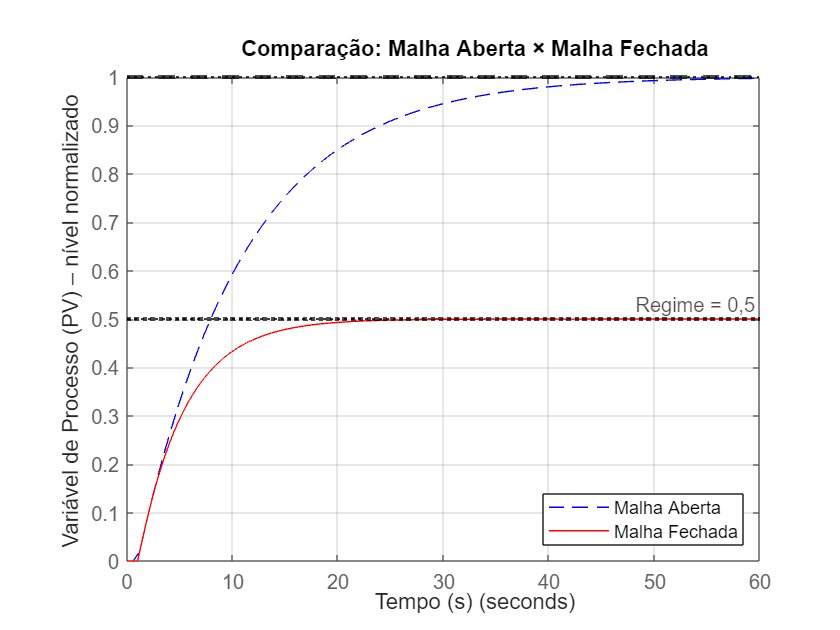

G_malha_aberta = Gp;
G_malha_fechada = feedback(G_malha_aberta, 1);   % H(s) = 1

figure('Name', 'Malha Aberta vs Malha Fechada', 'NumberTitle', 'off');
step(G_malha_aberta, 'b--', G_malha_fechada, 'r-', 60);
hold on;
% Linha do setpoint (SP = 1)
yline(1, 'k--', 'Setpoint (SP)', 'LineWidth', 2, 'LabelHorizontalAlignment', 'left');
% Anotação do valor de regime da malha fechada
yline(0.5, 'k:', 'Regime = 0,5', 'LineWidth', 2, 'LabelHorizontalAlignment', 'right');
hold off;

title('Comparação: Malha Aberta × Malha Fechada');
legend('Malha Aberta', 'Malha Fechada', ...
       'Location', 'southeast');
ylabel('Variável de Processo (PV) – nível normalizado');
xlabel('Tempo (s)');
grid on;

## **Interpretação**:

Em malha aberta a PV segue a entrada mas não corrige perturbações. 

Em malha fechada (apenas realimentação) a PV tende ao setpoint, mas ainda apresenta erro de regime se o processo não for do tipo 1. Com o controlador PID podemos eliminar esse erro e melhorar a dinâmica.

## Variáveis da malha – Exemplo gráfico

Simulação com um controlador proporcional simples para visualizar SP, PV, MV e erro.

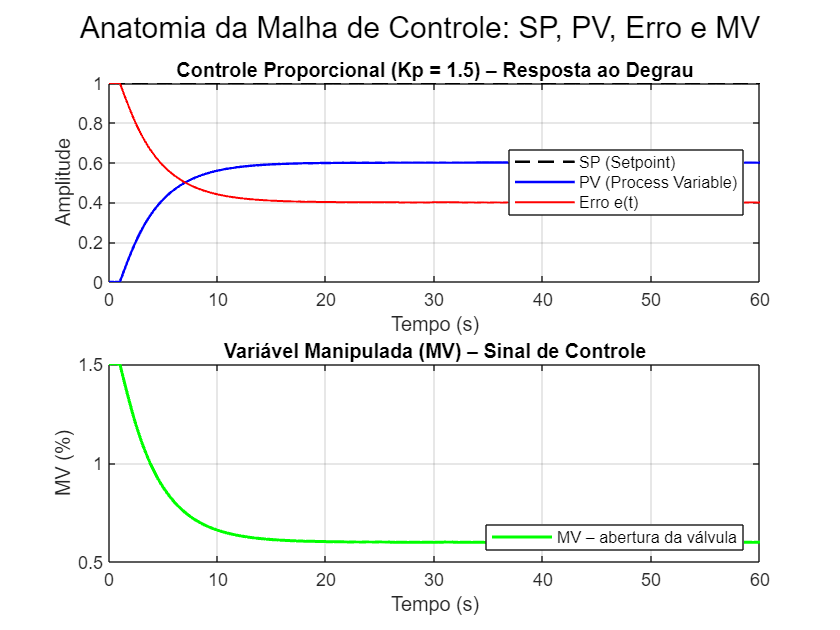

Kp_ex = 1.5;
C_ex = pid(Kp_ex, 0, 0);   % P puro
Gc_ex = feedback(C_ex * Gp, 1);
t = 0:0.1:60;
[y_ex, t_ex] = step(Gc_ex, t);
u_ex = Kp_ex * (1 - y_ex);   % MV proporcional ao erro (SP=1)

figure('Name', 'Variáveis da Malha', 'NumberTitle', 'off');
subplot(2,1,1);
plot(t_ex, ones(size(t_ex)), 'k--', 'LineWidth', 1.2); hold on;
plot(t_ex, y_ex, 'b-', 'LineWidth', 1.2);
plot(t_ex, 1 - y_ex, 'r-', 'LineWidth', 1);
title('Controle Proporcional (Kp = 1.5) – Resposta ao Degrau');
xlabel('Tempo (s)'); ylabel('Amplitude');
legend('SP (Setpoint)', 'PV (Process Variable)', 'Erro e(t)', ...
       'Location', 'east');
grid on;

subplot(2,1,2);
plot(t_ex, u_ex, 'g-', 'LineWidth', 1.5);
title('Variável Manipulada (MV) – Sinal de Controle');
xlabel('Tempo (s)'); ylabel('MV (%)');
legend('MV – abertura da válvula', 'Location', 'southeast');
grid on;
sgtitle('Anatomia da Malha de Controle: SP, PV, Erro e MV');

# O CONTROLADOR PID – CONCEITOS E ANALOGIAS (SEÇÃO III)

## Equação do Controlador PID


$$MV(t) = K_p \cdot e(t) + K_i \int_0^t e(\tau)d\tau + K_d \frac{de(t)}{dt}$$


## Termos:

- **Proporcional (P) – **reage ao erro **presente**.  

**Analogia: **motorista que corrige a direção proporcionalmente ao desvio.

- **Integral (I) – **acumula o erro **passado** e elimina o offset.  

**Analogia:** histórico do GPS que recalcula a rota para zerar o desvio acumulado.

- **Derivativo (D) – **antecipa o erro **futuro** (taxa de variação).  

**Analogia:** freio de emergência que age ao detectar aproximação rápida de obstáculo.

## Comparação visual: P, PI e PID

Projetamos três controladores para o mesmo processo e comparamos a resposta.

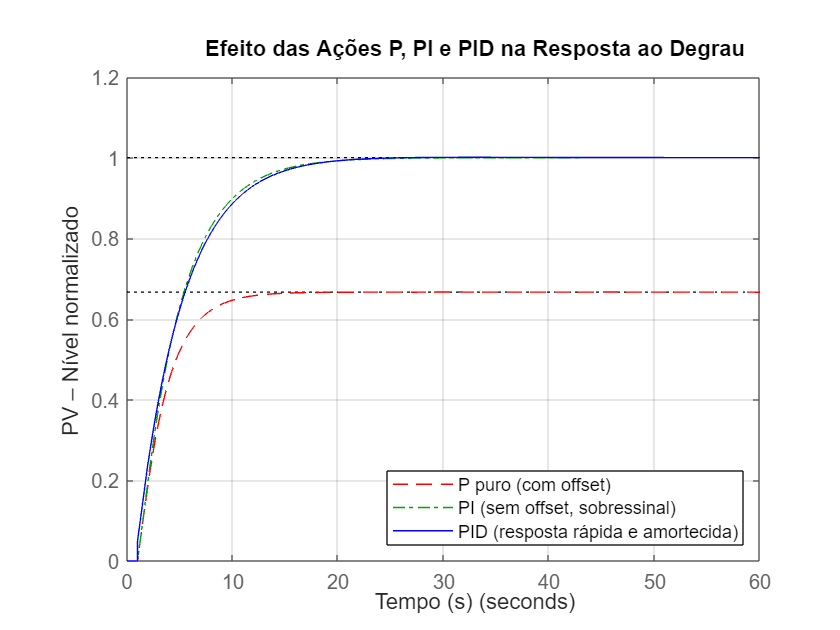

Kp_base = 2; Ki_base = 0.2; Kd_base = 0.5;

C_P    = pid(Kp_base, 0, 0);
C_PI   = pid(Kp_base, Ki_base, 0);
C_PID  = pid(Kp_base, Ki_base, Kd_base);

G_P   = feedback(C_P * Gp, 1);
G_PI  = feedback(C_PI * Gp, 1);
G_PID = feedback(C_PID * Gp, 1);

figure('Name', 'Comparação P, PI, PID', 'NumberTitle', 'off');
step(G_P, 'r--', G_PI, 'g-.', G_PID, 'b-', 60);
title('Efeito das Ações P, PI e PID na Resposta ao Degrau');
legend('P puro (com offset)', 'PI (sem offset, sobressinal)', ...
       'PID (resposta rápida e amortecida)', 'Location', 'southeast');
xlabel('Tempo (s)'); ylabel('PV – Nível normalizado');
grid on;

# Observações:

- **P puro: **resposta rápida, mas erro de regime permanente (offset).

- **PI:** elimina o offset, mas aumenta o sobressinal e o tempo de acomodação.

- **PID:** reduz sobressinal e tempo de acomodação graças à ação derivativa.

# SIMULAÇÃO INTERATIVA – AJUSTE EM TEMPO REAL DOS GANHOS PID

Nesta seção criamos uma interface gráfica interativa com sliders para **Kp, Ki, Kd**. A resposta ao degrau, a MV e o erro são atualizados dinamicamente.

**Recursos:** Uifigure, sliders, gráficos lado a lado. Execute a célula abaixo para iniciar o painel de controle.

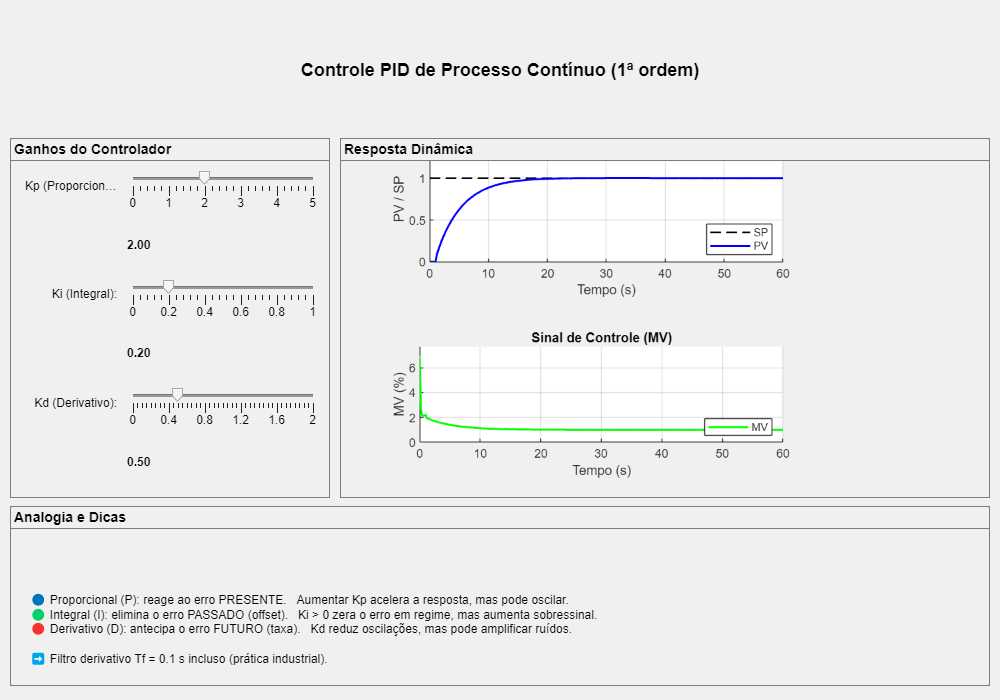

% Para executar a interface, chame a função passando o processo definido:
simulacao_interativa_pid(Gp);

#  MÉTODO DA CURVA DE REAÇÃO (MALHA ABERTA)

## Obtém a resposta ao degrau unitário

t = 0:0.1:50;
[y, t] = step(Gp, t);


##  Passo 1: Identificar o ponto de máxima inclinação (inflexão). Calcula a derivada numérica

dt_ = t(2) - t(1);
dy = diff(y) / dt_;

**A inclinação máxima ocorre em t=0, mas numericamente será próximo**

[slope_max, idx_max] = max(dy);  % inclinação máxima e seu índice
t_inf = t(idx_max);               % tempo no ponto de inflexão
y_inf = y(idx_max);               % valor da saída no ponto de inflexão


## Passo 2: Traçar a reta tangente no ponto de inflexão ---

Equação: y_tang = y_inf + slope_max * (t_tang - t_inf)

t_tang = linspace(0, 20, 100);
y_tang = y_inf + slope_max * (t_tang - t_inf);


## Passo 3: Determinar L (atraso aparente) e T (constante de tempo aparente) ---

 L é o instante em que a tangente cruza o eixo do tempo (y=0)

L = t_inf - y_inf / slope_max;

**T é o tempo necessário para a tangente ir de 0 até o valor final (1)**

T = (1 - 0) / slope_max;
fprintf('Inclinação máxima = %.4f\n', slope_max);

Inclinação máxima = 0.0995


fprintf('L (atraso aparente) = %.4f s\n', L);

L (atraso aparente) = 1.0000 s


fprintf('T (constante de tempo aparente) = %.4f s\n', T);

T (constante de tempo aparente) = 10.0501 s


fprintf('Como L ≈ 0, os parâmetros PID tendem a infinito. Método não aplicável.\n\n');

Como L ≈ 0, os parâmetros PID tendem a infinito. Método não aplicável.



**Gráfico da curva de reação com a tangente**

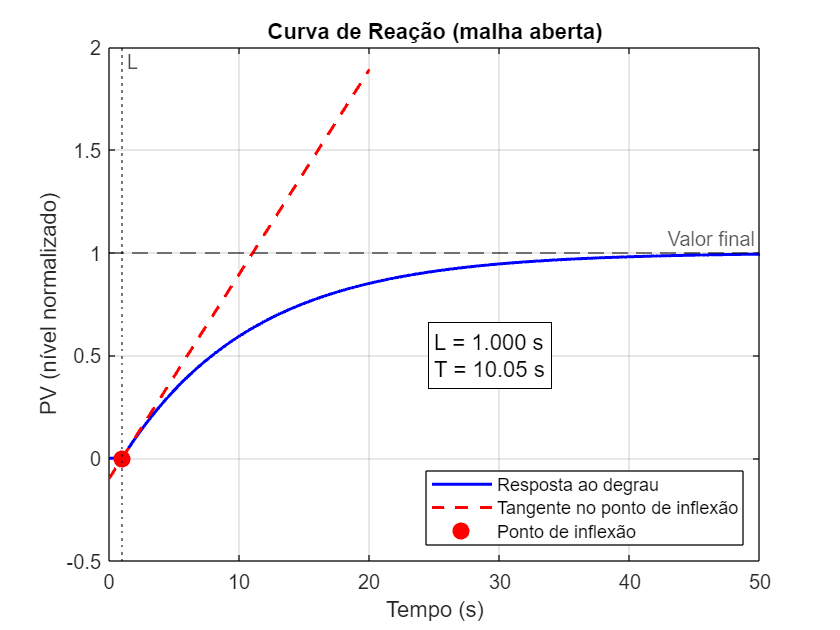

figure('Name', 'Curva de Reação - Malha Aberta', 'NumberTitle', 'off');
plot(t, y, 'b-', 'LineWidth', 1.5); hold on;
plot(t_tang, y_tang, 'r--', 'LineWidth', 1.5);
plot(t_inf, y_inf, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
xline(L, 'k:', 'L', 'LabelOrientation', 'horizontal');
yline(1, 'k--', 'Valor final');
xlabel('Tempo (s)');
ylabel('PV (nível normalizado)');
title('Curva de Reação (malha aberta)');
legend('Resposta ao degrau', 'Tangente no ponto de inflexão', 'Ponto de inflexão', ...
       'Location', 'southeast');
grid on;
text(25, 0.5, sprintf('L = %.3f s\nT = %.2f s', L, T), 'FontSize', 11, ...
     'BackgroundColor', 'w', 'EdgeColor', 'k');

**Cálculo dos parâmetros PID conforme tabela de Ziegler-Nichols**

Kp_ma = 1.2 * T / L;
Ti_ma = 2 * L;
Td_ma = 0.5 * L;
Ki_ma = Kp_ma / Ti_ma;
Kd_ma = Kp_ma * Td_ma;
fprintf('Controlador PID (malha aberta):\nKp = %.2f\nKi = %.2f\nKd = %.2f\n\n',Kp_ma,Ki_ma,Kd_ma);

Controlador PID (malha aberta):
Kp = 12.06
Ki = 6.03
Kd = 6.03



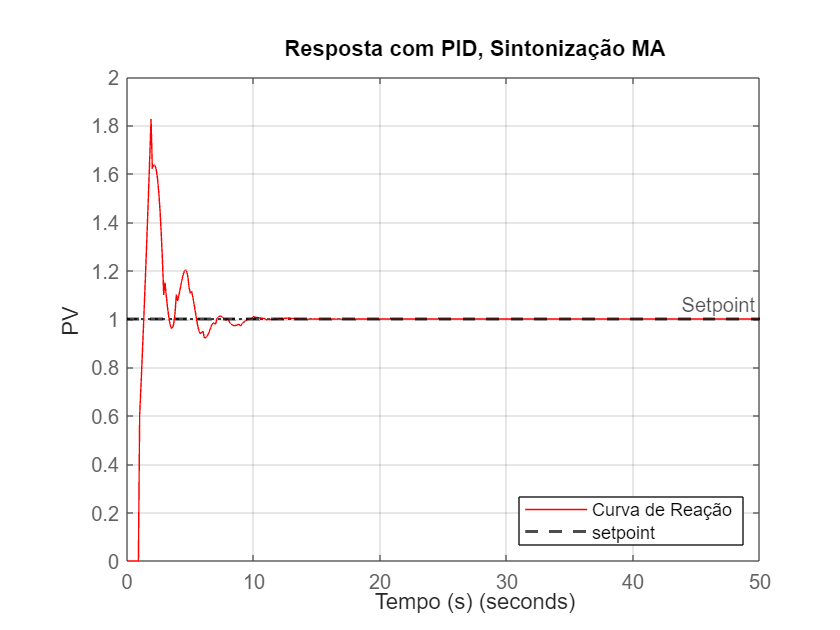

C_ma = pid(Kp_ma, Ki_ma, Kd_ma);
Gcl_ma = feedback(C_ma * Gp, 1);
figure;
step(Gcl_ma, t, 'r-');
yline(1,'k--','Setpoint','LineWidth', 1.5);
xlabel('Tempo (s)'); ylabel('PV');
title('Resposta com PID, Sintonização MA');
legend('Curva de Reação','setpoint','Location','southeast');
grid on;

# MÉTODO DO GANHO CRÍTICO (MALHA FECHADA)

## Varre diversos ganhos proporcionais e observa a resposta em malha fechada

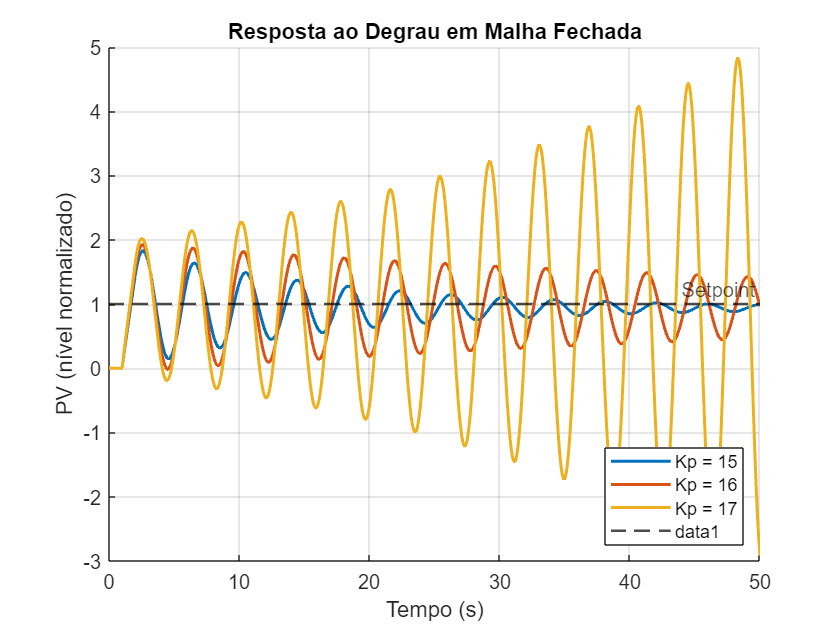


Kp_teste = [15 16 17];  % ganhos a testar
cores = lines(length(Kp_teste));

figure('Name', 'Respostas em Malha Fechada - Variação de Kp', 'NumberTitle', 'off');
hold on;
for i = 1:length(Kp_teste)
    Kp = Kp_teste(i);
    C = pid(Kp, 0, 0);
    Gcl = feedback(C * Gp, 1);
    % Obtém os dados da resposta ao degrau
    [y_step, t_step] = step(Gcl, t);
    % Plota com as propriedades desejadas
    plot(t_step, y_step, 'Color', cores(i,:), 'LineWidth', 1.5, ...
         'DisplayName', sprintf('Kp = %d', Kp));
end
yline(1, 'k--', 'Setpoint', 'LineWidth', 1.2);
xlabel('Tempo (s)');
ylabel('PV (nível normalizado)');
title('Resposta ao Degrau em Malha Fechada');
legend('Location', 'southeast');
grid on;

## Análise para encontrar ganho crítico

Ku=16;
Pu=17.8-14;
Kp_mf = 0.6*Ku;
Ti_mf = 0.5*Pu;
Td_mf = 0.125*Pu;
Ki_mf = Kp_mf/Ti_mf;
Kd_mf = Kp_mf*Td_mf;
fprintf('Ganho crítico:\n Ku=%.2f\n Pu=%.2f\n\nPID:\n Kp=%.2f\n Ki=%.2f\n Kd=%.2f\n', ...
        Ku, Pu, Kp_mf, Ki_mf, Kd_mf);

Ganho crítico:
 Ku=16.00
 Pu=3.80

PID:
 Kp=9.60
 Ki=5.05
 Kd=4.56


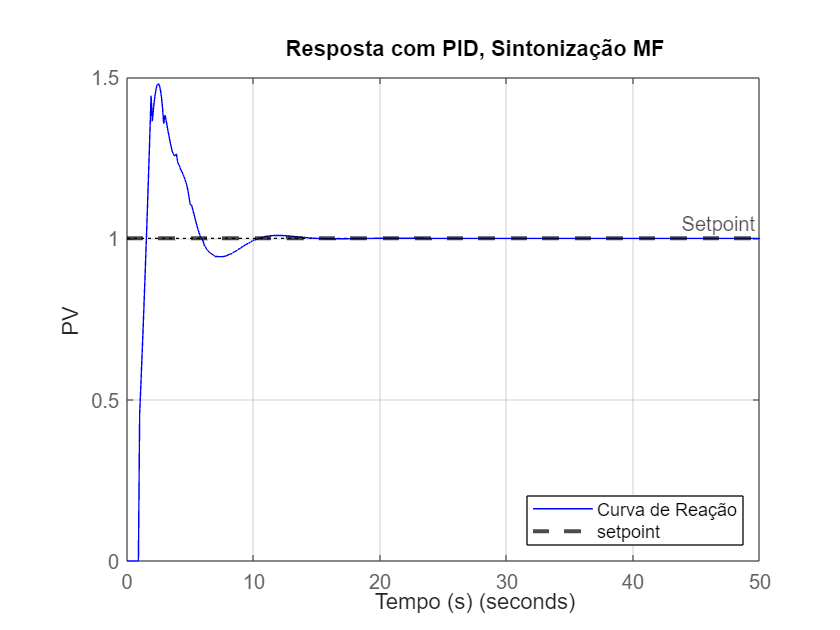

C_mf = pid(Kp_mf, Ki_mf, Kd_mf);
Gcl_mf = feedback(C_mf * Gp, 1);
figure;
step(Gcl_mf, t, 'b-');
yline(1,'k--','Setpoint','LineWidth', 2);
xlabel('Tempo (s)'); ylabel('PV');
title('Resposta com PID, Sintonização MF');
legend('Curva de Reação','setpoint','Location','southeast');
grid on;

# Comparação das respostas

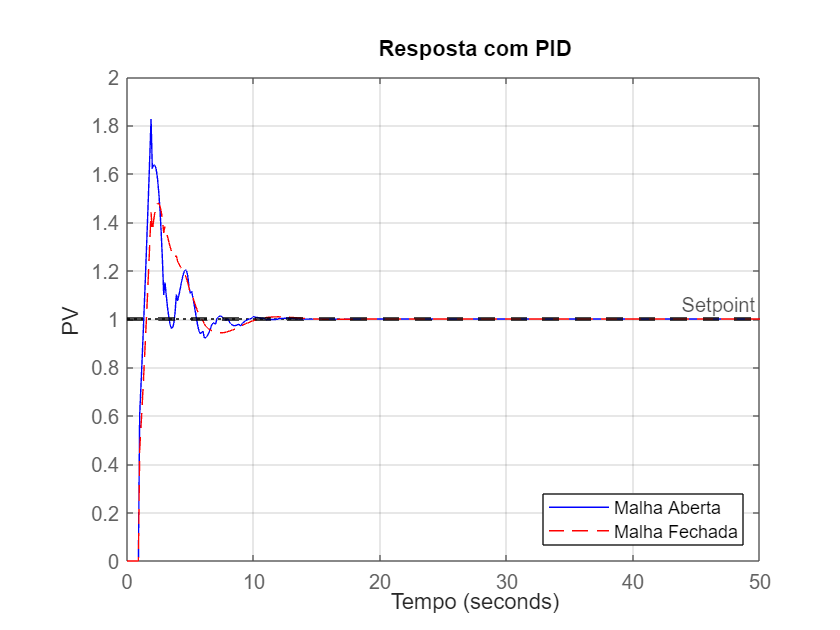

C_ma = pid(Kp_ma, Ki_ma, Kd_ma);
C_mf = pid(Kp_mf, Ki_mf, Kd_mf);
Gcl_ma = feedback(C_ma * Gp, 1);
Gcl_mf = feedback(C_mf * Gp, 1);
figure;
step(Gcl_ma, t, 'b-', Gcl_mf, t, 'r--');
yline(1,'k--','Setpoint','LineWidth', 2);
xlabel('Tempo'); ylabel('PV');
title('Resposta com PID');
legend('Malha Aberta','Malha Fechada','Location','southeast');
grid on;

function simulacao_interativa_pid(Gp)
    % Gp: função de transferência do processo (tf)
    
    % Cria figura com layout
    fig = uifigure('Name', 'Ajuste Interativo do PID - Simulação Didática', ...
                   'Position', [100 100 1000 700]);
    
    % Grades de layout
    gl = uigridlayout(fig, [3, 3], ...
        'RowHeight', {'1x', '3x', '1.5x'}, ...
        'ColumnWidth', {'1x', '1x', '1x'});
    
    % Título
    lblTitulo = uilabel(gl, ...
        'Text', 'Controle PID de Processo Contínuo (1ª ordem)', ...
        'FontSize', 18, 'FontWeight', 'bold', ...
        'HorizontalAlignment', 'center');
    lblTitulo.Layout.Row = 1;
    lblTitulo.Layout.Column = [1 3];
    
    % Painel dos sliders
    pnlSliders = uipanel(gl, 'Title', 'Ganhos do Controlador', ...
        'FontSize', 14, 'FontWeight', 'bold');
    pnlSliders.Layout.Row = 2;
    pnlSliders.Layout.Column = 1;
    
    % Layout interno do painel
    glSliders = uigridlayout(pnlSliders, [7, 2], ...
        'RowHeight', {30, 30, 30, 30, 30, 30, 20}, ...
        'ColumnWidth', {'1x', '2x'});
    
    % ----- Linha 1: Kp -----
    uilabel(glSliders, 'Text', 'Kp (Proporcional):', ...
        'HorizontalAlignment', 'right', 'FontSize', 12);
    sldKp = uislider(glSliders, 'Limits', [0 5], 'Value', 2.0);
    sldKp.Layout.Row = 1; sldKp.Layout.Column = 2;
    valKp = uilabel(glSliders, 'Text', sprintf('%.2f', sldKp.Value), ...
        'FontSize', 12, 'FontWeight', 'bold', ...
        'HorizontalAlignment', 'left');
    valKp.Layout.Row = 2; valKp.Layout.Column = 2;
    
    % ----- Linha 3: Ki -----
    uilabel(glSliders, 'Text', 'Ki (Integral):', ...
        'HorizontalAlignment', 'right', 'FontSize', 12);
    sldKi = uislider(glSliders, 'Limits', [0 1], 'Value', 0.2);
    sldKi.Layout.Row = 3; sldKi.Layout.Column = 2;
    valKi = uilabel(glSliders, 'Text', sprintf('%.2f', sldKi.Value), ...
        'FontSize', 12, 'FontWeight', 'bold', ...
        'HorizontalAlignment', 'left');
    valKi.Layout.Row = 4; valKi.Layout.Column = 2;
    
    % ----- Linha 5: Kd -----
    uilabel(glSliders, 'Text', 'Kd (Derivativo):', ...
        'HorizontalAlignment', 'right', 'FontSize', 12);
    sldKd = uislider(glSliders, 'Limits', [0 2], 'Value', 0.5);
    sldKd.Layout.Row = 5; sldKd.Layout.Column = 2;
    valKd = uilabel(glSliders, 'Text', sprintf('%.2f', sldKd.Value), ...
        'FontSize', 12, 'FontWeight', 'bold', ...
        'HorizontalAlignment', 'left');
    valKd.Layout.Row = 6; valKd.Layout.Column = 2;
    
    % ----- Painel dos gráficos -----
    pnlPlots = uipanel(gl, 'Title', 'Resposta Dinâmica', ...
        'FontSize', 14, 'FontWeight', 'bold');
    pnlPlots.Layout.Row = 2;
    pnlPlots.Layout.Column = [2 3];
    
    % Eixos para os gráficos - CORREÇÃO
    ax1 = uiaxes(pnlPlots, 'Position', [50 200 400 180]);
    xlabel(ax1, 'Tempo (s)');
    ylabel(ax1, 'PV / SP');
    title(ax1, 'Resposta ao Degrau (Setpoint = 1)');
    grid(ax1, 'on');
    hold(ax1, 'on');
    
    ax2 = uiaxes(pnlPlots, 'Position', [50 20 400 150]);
    xlabel(ax2, 'Tempo (s)');
    ylabel(ax2, 'MV (%)');
    title(ax2, 'Sinal de Controle (MV)');
    grid(ax2, 'on');
    hold(ax2, 'on');
    
    % Linha de setpoint
    t_plot = (0:0.2:60)';
    sp_line = plot(ax1, [0 60], [1 1], 'k--', 'LineWidth', 1.2);
    pv_line = plot(ax1, nan, nan, 'b-', 'LineWidth', 1.5);
    mv_line = plot(ax2, nan, nan, 'g-', 'LineWidth', 1.5);
    
    legend(ax1, {'SP', 'PV'}, 'Location', 'southeast');
    legend(ax2, {'MV'}, 'Location', 'southeast');
    
    % ----- Função de atualização -----
    function updatePlot(~,~)
        Kp = sldKp.Value;
        Ki = sldKi.Value;
        Kd = sldKd.Value;
        
        valKp.Text = sprintf('%.2f', Kp);
        valKi.Text = sprintf('%.2f', Ki);
        valKd.Text = sprintf('%.2f', Kd);
        
        % --- FILTRO DERIVATIVO (evita modelo impróprio) ---
        Tf = 0.1;   % constante de tempo do filtro (ajustável)
        C = pid(Kp, Ki, Kd, Tf);   % controlador PID com filtro
        
        % Malha fechada para a saída (PV)
        Gcl = feedback(C * Gp, 1);
        [y, t] = step(Gcl, t_plot);
        
        % Malha fechada para o sinal de controle (MV)
        % Transferência: MV/SP = C / (1 + C*Gp)
        G_MV = C / (1 + C * Gp);
        [u, ~] = step(G_MV, t_plot);
        
        % Atualiza os gráficos
        pv_line.XData = t;
        pv_line.YData = y;
        mv_line.XData = t;
        mv_line.YData = u;
        
        % Ajuste dos limites dos eixos
        ylim(ax1, [0 1.5]);
        ylim(ax2, [min(0, min(u)*1.1), max(2, max(u)*1.1)]);
    end
    
    % Atribui callbacks
    sldKp.ValueChangedFcn = @updatePlot;
    sldKi.ValueChangedFcn = @updatePlot;
    sldKd.ValueChangedFcn = @updatePlot;
    
    % Chamada inicial
    updatePlot();
    
    % ----- Painel de informações complementares -----
    pnlInfo = uipanel(gl, 'Title', 'Analogia e Dicas', ...
        'FontSize', 14, 'FontWeight', 'bold');
    pnlInfo.Layout.Row = 3;
    pnlInfo.Layout.Column = [1 3];
    
    txtInfo = uilabel(pnlInfo, ...
        'Text', sprintf([ ...
        '🔵 Proporcional (P): reage ao erro PRESENTE.   Aumentar Kp acelera a resposta, mas pode oscilar.\n' ...
        '🟢 Integral (I): elimina o erro PASSADO (offset).   Ki > 0 zera o erro em regime, mas aumenta sobressinal.\n' ...
        '🔴 Derivativo (D): antecipa o erro FUTURO (taxa).   Kd reduz oscilações, mas pode amplificar ruídos.\n\n' ...
        '➡️ Filtro derivativo Tf = 0.1 s incluso (prática industrial).']), ...
        'FontSize', 12, 'HorizontalAlignment', 'left', ...
        'VerticalAlignment', 'top', 'Position', [20 20 950 80]);
end